# Two-photon microscopy data analysis

This notebook is designed to analyze data obtained from two-photon microscopy, specifically for the Cold Spring Harbor Laboratory (CSHL) Drosophila Neurobiology course.

The analysis will focus on various aspects of the collected data, including visualizing the volumes, registering the volumes, image processing, quantification of neuronal activity, and visualization of results.

The goal is to provide a short introduction to analyzing datasets obtained from two-photon microscopy. 

## Setup libraries and folder locations

Here I load the required libraries, setup the data folders, etc. 

% Set folder names
curr_folder = pwd;
repo_folder = fullfile(curr_folder, '..');
data_folder = fullfile(repo_folder, 'data');

% Dataset name
dataset_name = '20240706a_00004_00001.tif'

dataset_name = '20240706a_00004_00001.tif'


% Load external libraries (that in in toolbox)
addpath(genpath(fullfile(pwd, 'toolbox/')));

## Loading and visualization datasets

In this section, we will load the dataset and visualize the volume as well as the linked metadata acquired during imaging. We will be using the scanimage library to load the tiff.

The below guide assumes that the two-photon microscope you are using saves the data as TIFF files (generally true as this is the default format).

### Load dataset

% Import Tiff Reader
import ScanImageTiffReader.ScanImageTiffReader;

% Setup reader to load dataset
reader = ScanImageTiffReader(fullfile(data_folder, dataset_name));

% Load dataset
volumes = reader.data(); % Load the volumes from the TIFF dataset
metadata = reader.metadata(); % Load metadata


### Visualizing dataset

Volumes are stored as 3D arrays, i.e. a stack of images (like the ImageJ / Fiji visualization). The first two dimensions are the image resolution, the third dimension is number of such images that are acquired. They are technically not volumes as there is no information about the depth of acqusition for each image.

We can do some exploratory investigation by looking at the dimensions, the number of images in the stack and visualize individual images.

Our dataset has the following dimensions:

disp(['Size of volumes: ', num2str(size(volumes))]);

Size of volumes: 128    128  17000


To visualize the first image:

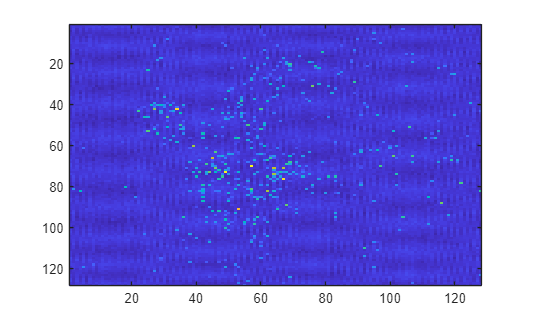

imagesc(volumes(:, :, 1)); % Read as display all pixels in the row, column, of the first stack